# Solution of the NLS by the split-step method

Solve the equation


$$i\frac{\partial \psi }{\partial z}+\frac{1}{2}\frac{\partial^2 \psi }{{\partial x}^2 }+{|\psi |}^2 \psi =0$$


## By Claudio, January 2019

clearvars

## Grid Parameters 

$x_n =-\frac{\Delta x}{2}+\left(n-1\right)\text{ }\mathrm{dx}$ with $n=1,2,\ldotp \ldotp \ldotp ,n_x$


$$\mathrm{dx}=\frac{\Delta x}{n_x -1}$$


we propagate from $z=0$ to $z=\mathrm{zmax}$, we make nplots during evolution and nz steps between plotz

the size of the step size dz is 


$$\mathrm{dz}=\frac{\mathrm{zmax}}{\left(\mathrm{nz}-1\right)\left(\mathrm{nplots}-1\right)}$$


Deltax=15;            	    % windows 
nplot=100;		    % plot number
nz=100;			    % step between plots
zmax=pi;	            % length
nx=256;                   % number of points along x

## Initial condition parameters


$$\psi \left(x,z=0\right)=N\text{ }\mathrm{sech}\left(x\right)$$


N=6; % soliton number for sech input

## Grid definition


$$x_n =-\frac{\Delta x}{2}+n\text{ }\mathrm{dx}$$



$$\mathrm{dx}=\frac{\Delta x}{n_x -1}$$


zstep=zmax/(nz-1)/(nplot-1);   									
xmin=-Deltax/2; 
zplot=linspace(0,zmax,nplot+1); %points along z  per plot
ix=1:nx; x=xmin+(ix-1)*Deltax/(nx-1); xs=(ix-nx/2)/Deltax; 	%point in x

## Propagator for the linear part


$$e^{\frac{i\text{ }k^{2\text{ }} \text{ }}{2}\frac{\text{dz}}{2}}$$



$$k_n =n\text{ }\mathrm{dk}$$



$$\mathrm{dk}=\frac{1}{\Delta x}$$


ntx=0;
xx=zeros(nx,1);
dfx=1/Deltax;
% first positive and then negative solutions
for n=1:nx
  it=n-ntx-1;
  xx(n)=2*pi*dfx*it;
  if(n-nx/2==0); ntx=nx; end
end
arg1 = -(1/2)*(xx.^2)*zstep/2; 
conv1 = cos(arg1)+1i.*sin(arg1); % exp(i k^2 dz*0.5)

## Set input field profile


$$\psi \left(x,z=0\right)=N\text{ }\mathrm{sech}\left(x\right)$$


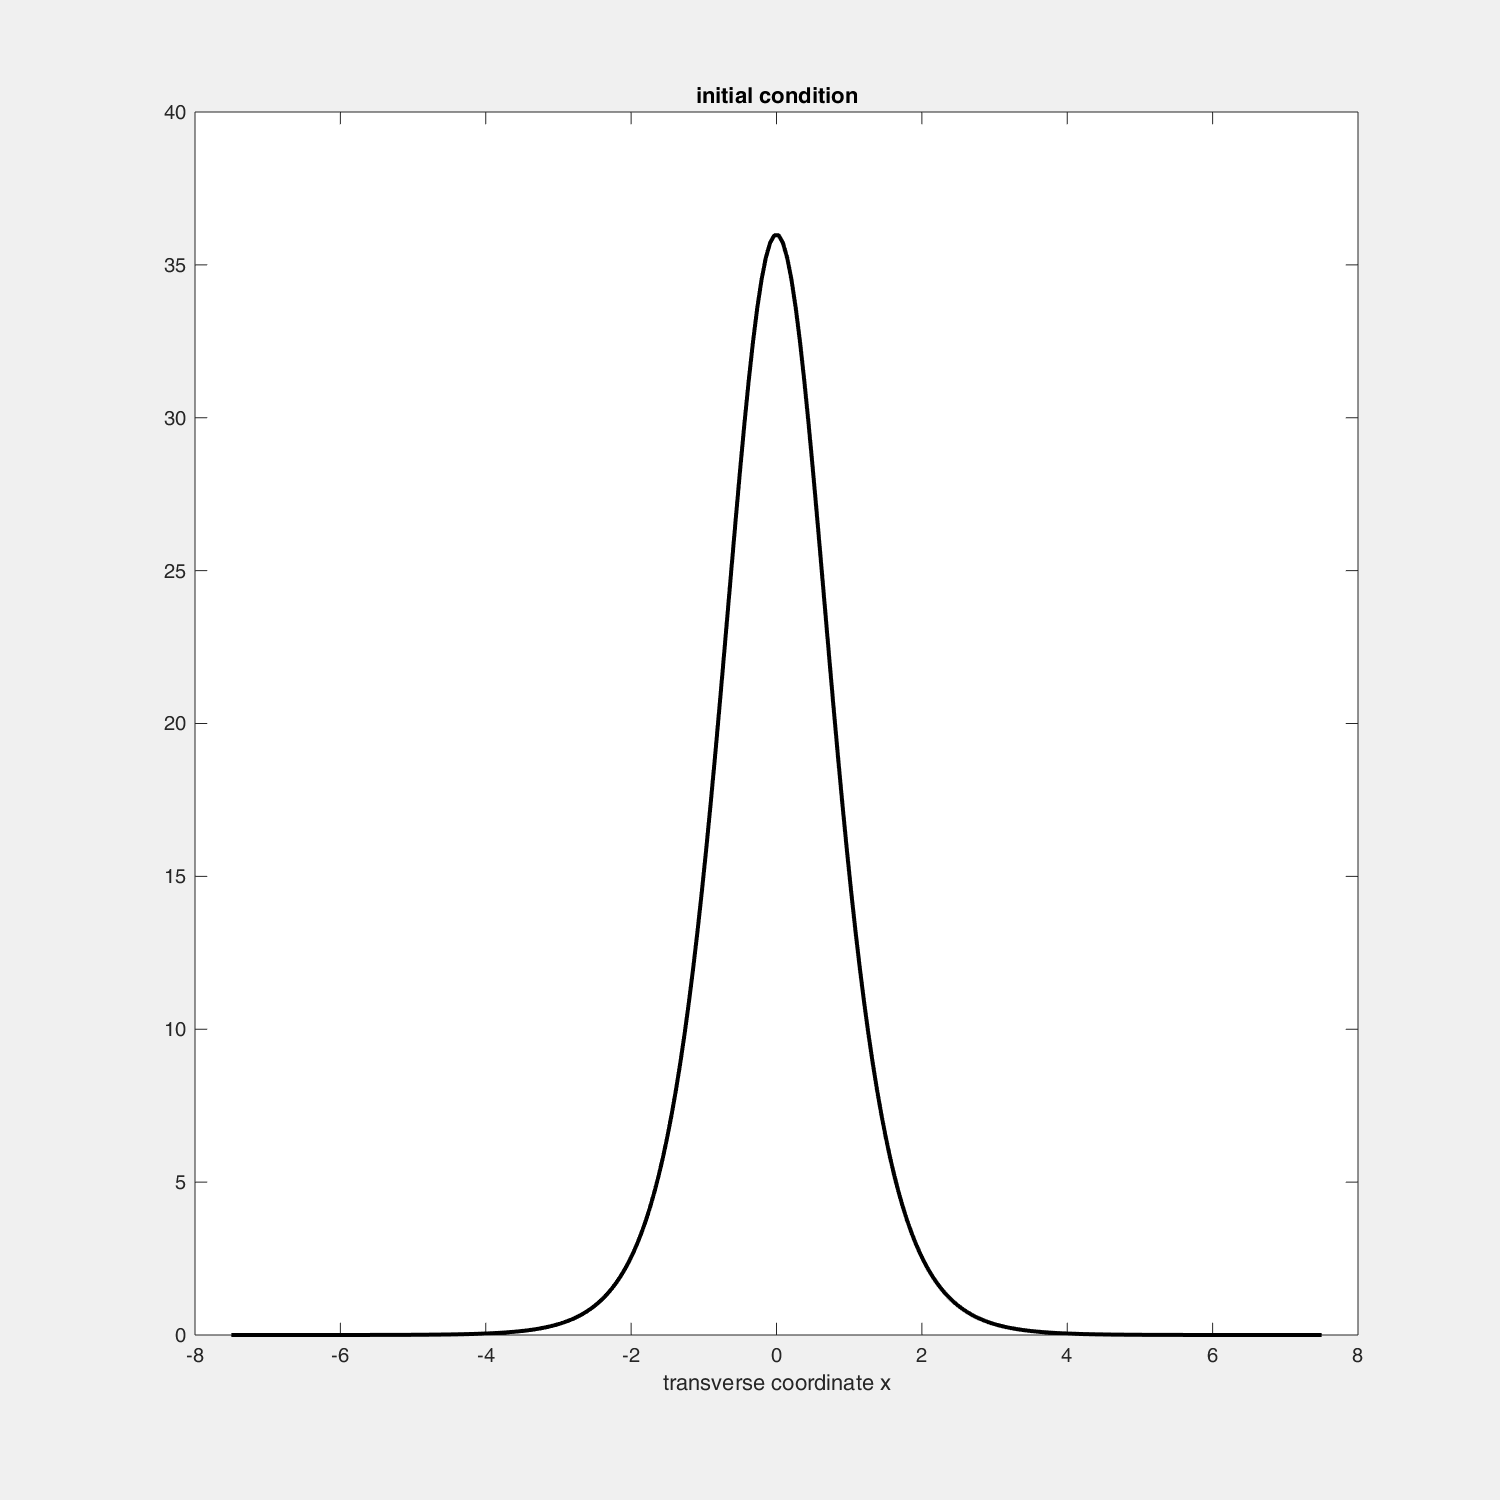

psi0=N*sech(x);
%psi=N*exp(-x.^20);
%psi=N*exp(-x.^2);
figure('visible','on','position',[400 100 1000 1000])
plot(x,abs(psi0).^2,'linewidth',2,'color','black')
xlabel('transverse coordinate x')
title('initial condition')

## Main loop

tic
zi=0; zf=zstep; np=0; 
fig1=figure('visible','on','position',[400 100 1000 1000])

fig1 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [400 100 1000 1000]
       Units: 'pixels'

  Show all properties


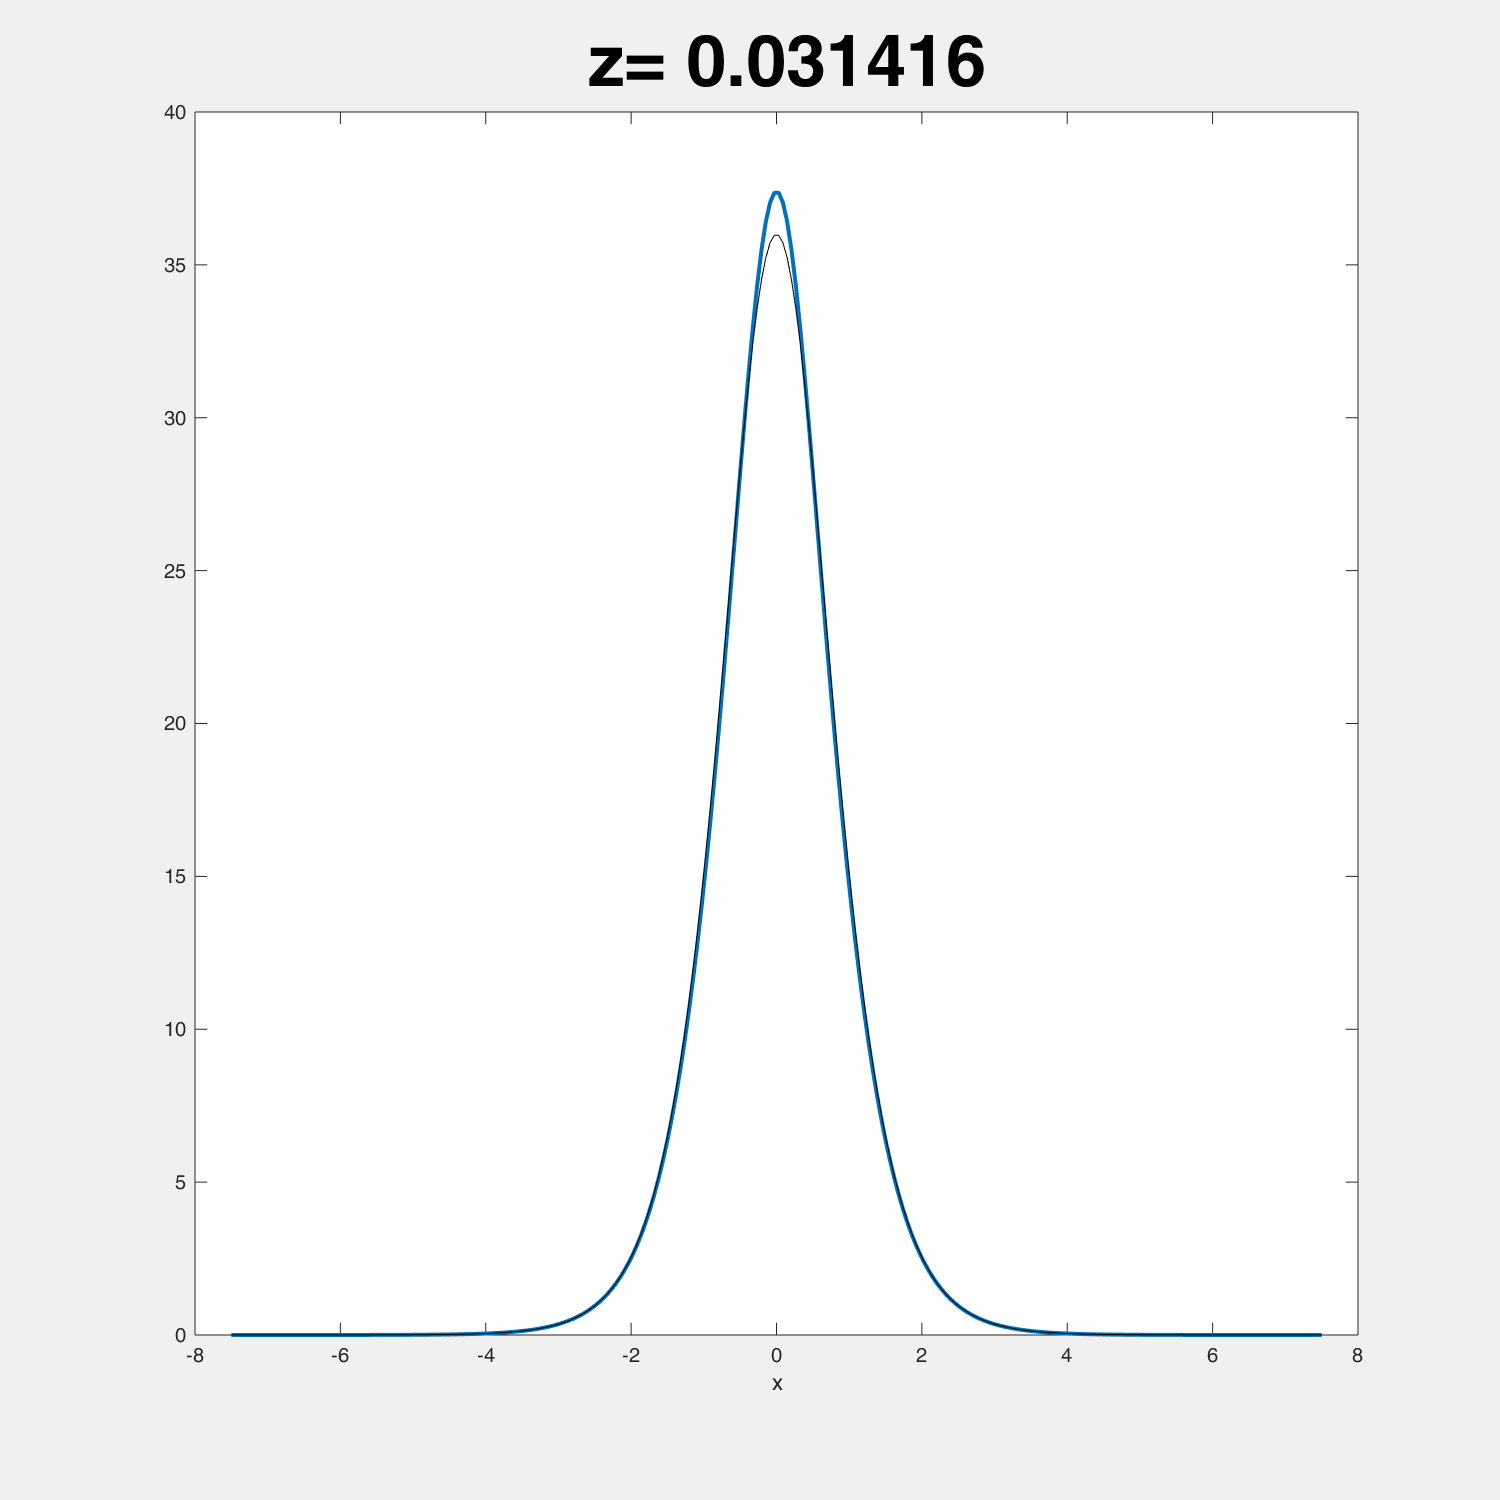

ax1=axes;

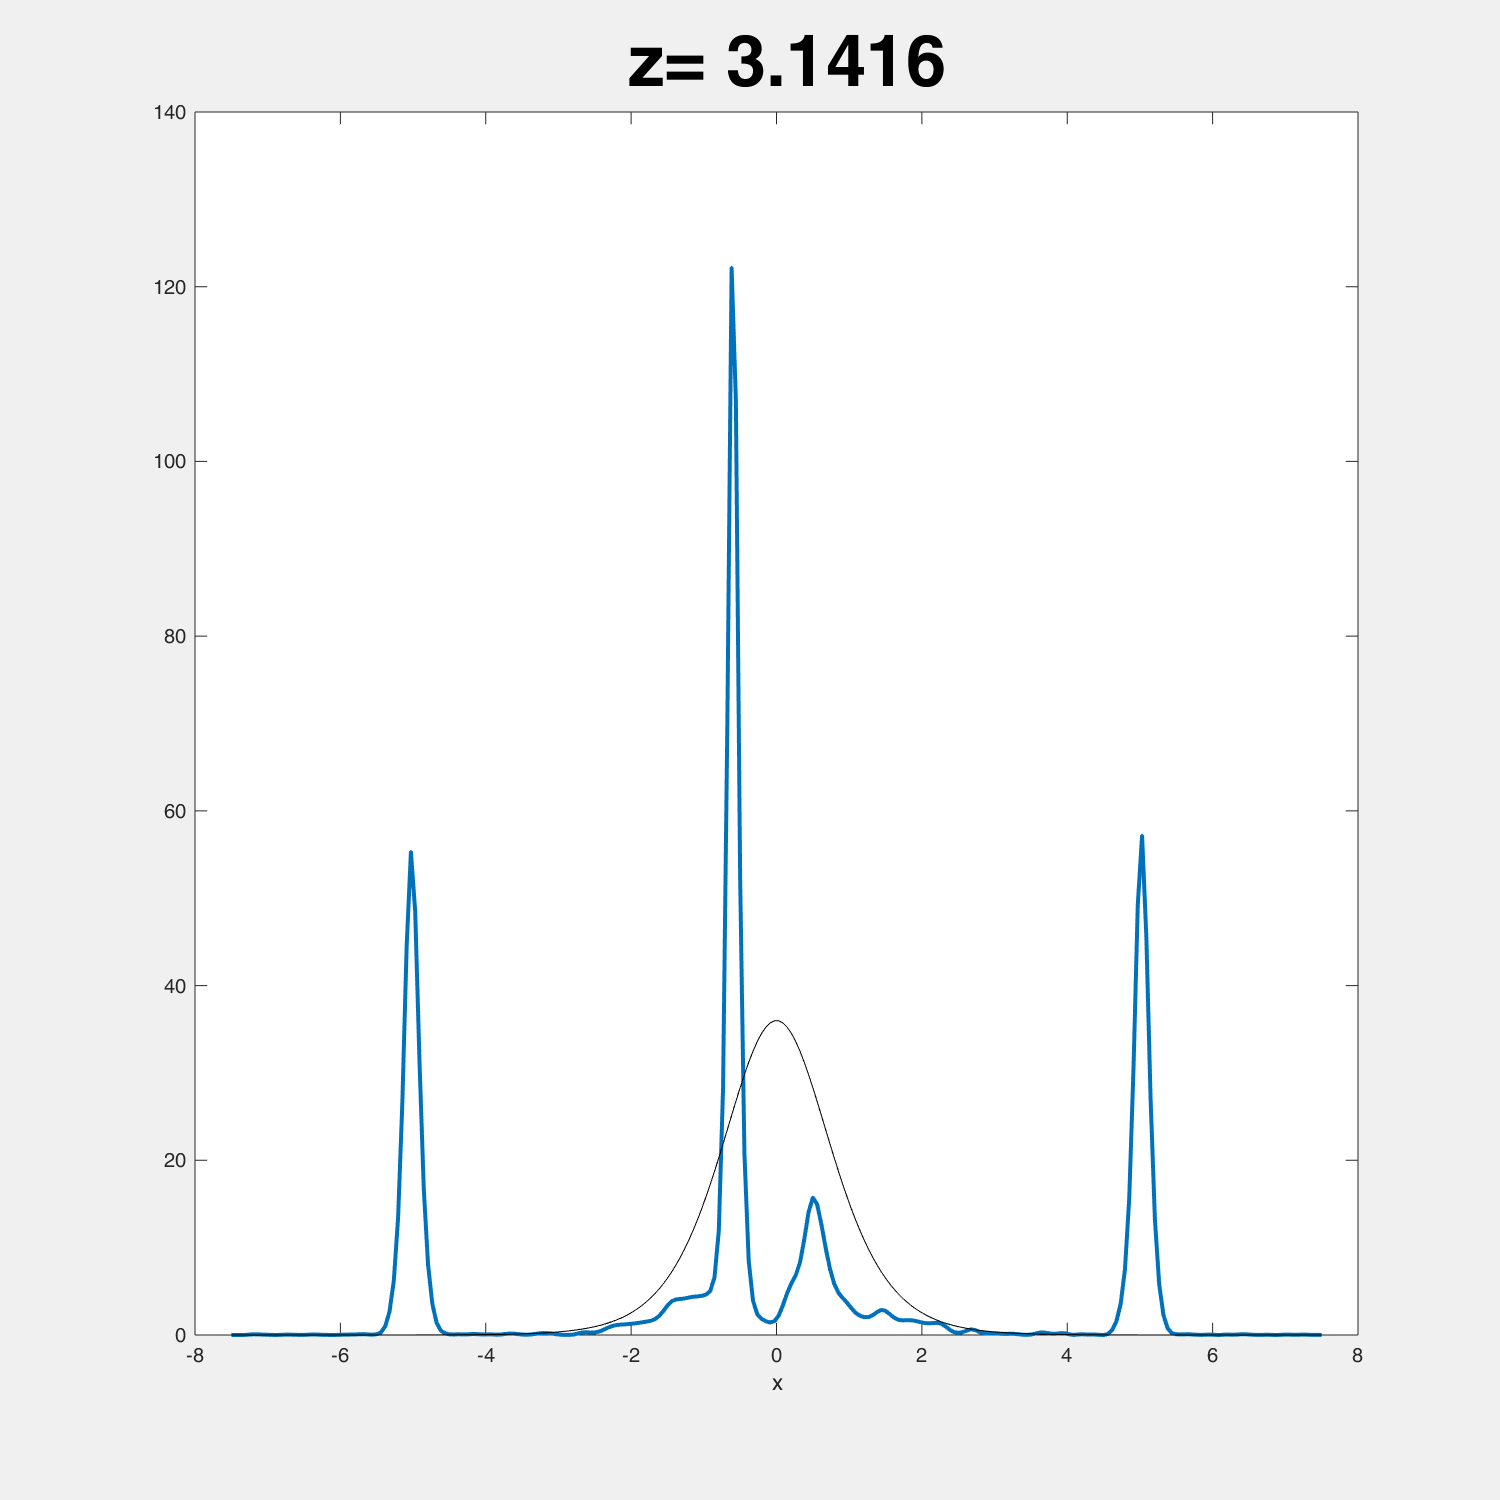

u2D=zeros(np+1,nx);
u2D(1,:)=psi0(:);
u=psi0(:);
for np=1:nplot
  for h=1:nz
    %%%%%%%%%%%%%%%%%%% DISPERSIVE HALF STEP %%%%%%%%%%%%%%%%%%%%%%%%%%%%    
    fu=fft(u,nx); fu=fu.*conv1; u=ifft(fu,nx);
    %%%%%%%%%%%%%%%%%%  ONE NONLINEAR STEP 
    u=u.*exp(1i*abs(u).^2*zstep);
    %%%%%%%%%%%%%%%%%%% DISPERSIVE HALF STEP %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    fu=fft(u,nx); fu=fu.*conv1; u=ifft(fu,nx);
  end
  %%%%%%%%%%%%%%%%%%   NEXT PLOT   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
  u2D(np+1,:)=u(:); 
  fase=unwrap(angle(u));
  plot(ax1,x,abs(u).^2,'linewidth',2),
  hold(ax1,'on')
  plot(x,abs(psi0).^2,'color','k'),
  hold(ax1,'off')
  title([' z= ' num2str(zplot(np+1))],'fontsize',36)
  xlabel('x')
  drawnow
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
toc

Elapsed time is 10.706897 seconds.


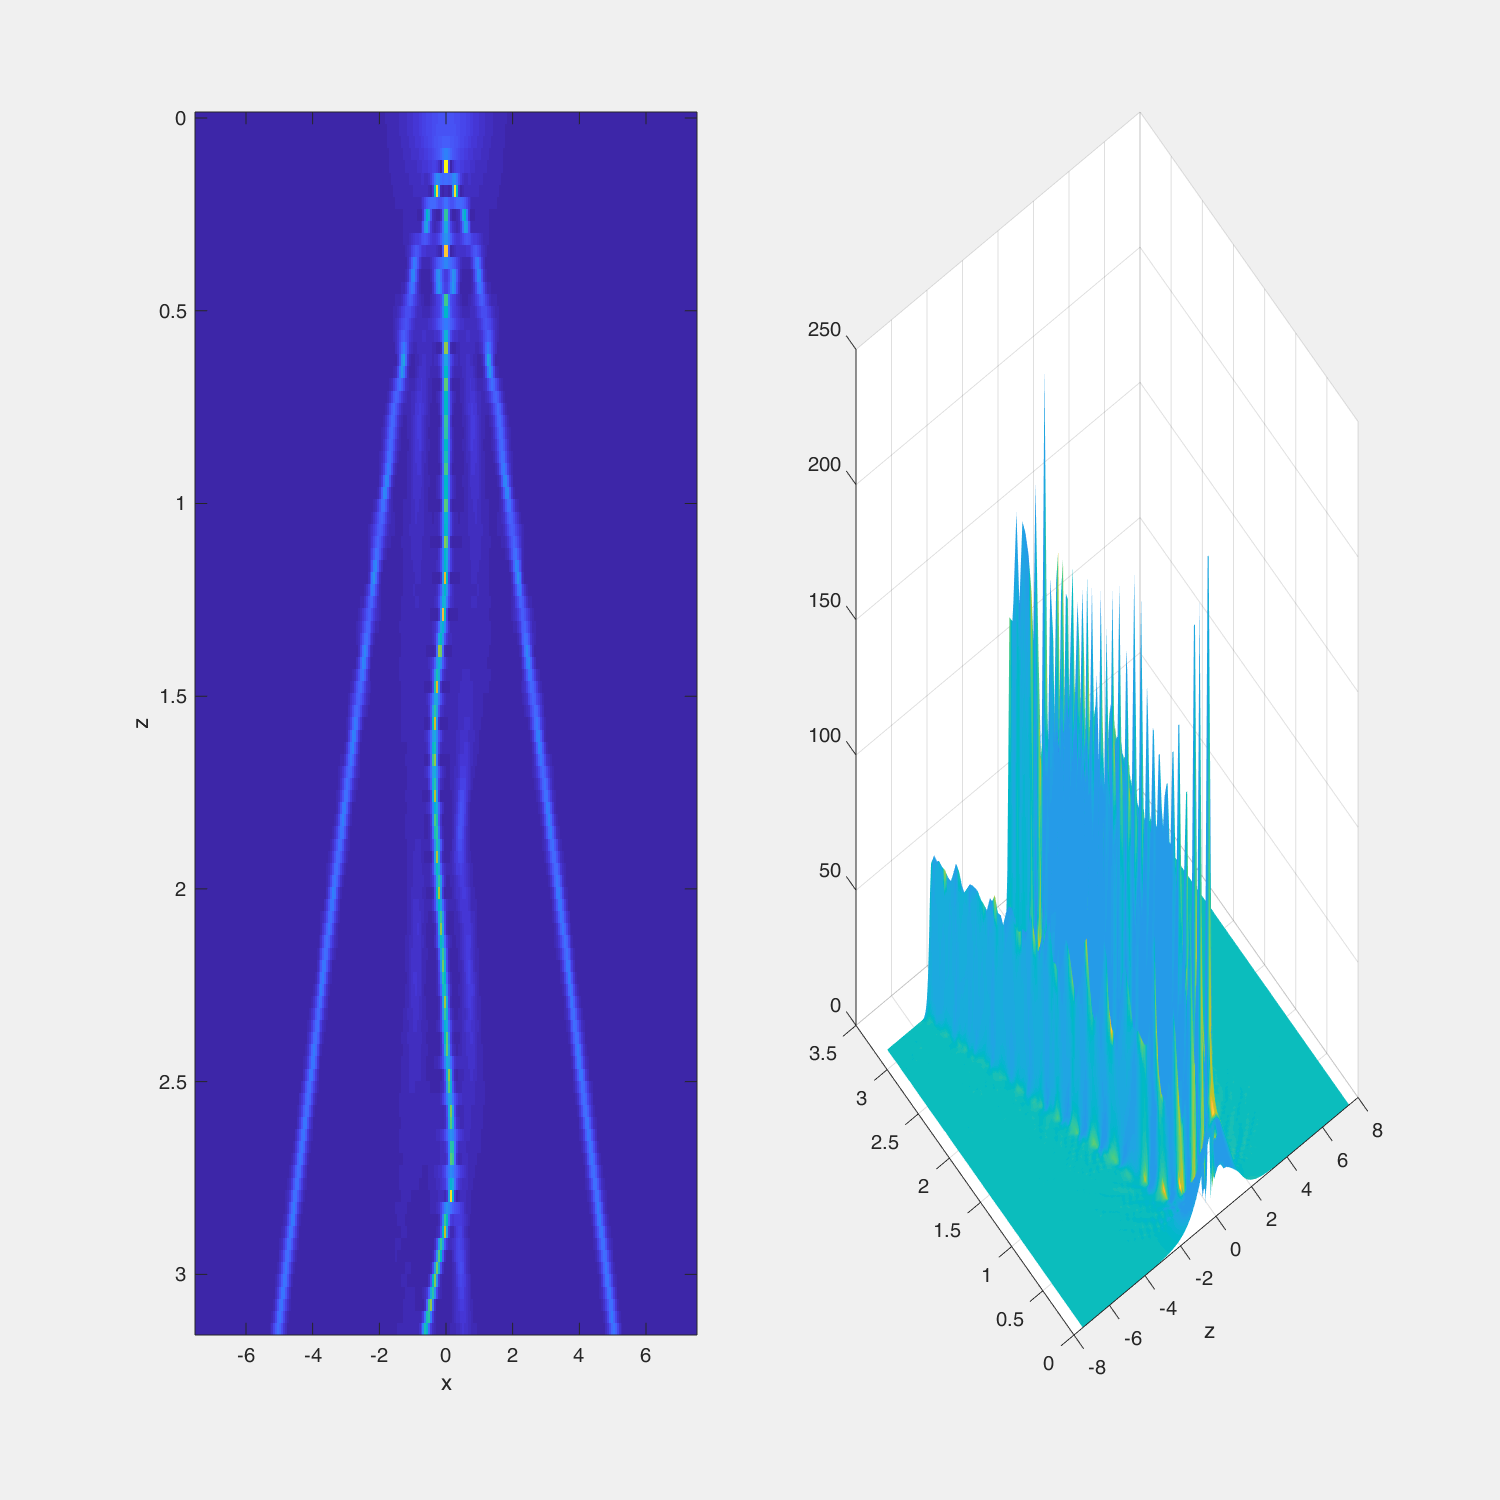

%% 3D plots			
figure('Visible','on','position',[150 100 1000 1000])
subplot(121)
imagesc(x,zplot,abs(u2D).^2),shading interp
xlabel('x')
ylabel('z')
subplot(122)
surfl(x,zplot,abs(u2D).^2),shading interp
xlabel('z')